For the grid world environment:

- The search area is a `12x12` grid with obstacles.

- The observation for each agent is a `12x12x4` image.

- The discrete action set contains five actions `(WAIT=0, UP=1, DOWN=2, LEFT=3, RIGHT=4)`.

- The simulation terminates when the grid is fully explored or the maximum number of steps is reached.

At each time step, agents receive the following rewards:

- `+2` for moving to a previously unexplored cell (white).

- `-1` for an illegal action (attempt to move outside the boundary or collide against other robots and obstacles).

- `-1` for an action that results in no motion (lazy penalty).

- `-0.5` for moving to an explored cell.

- `+100` if the grid is fully explored.

% Set the randomization flag
rng(0)
randomizeObstacles = false; % Set to 'false' to use fixed obstacle positions

% Define the size of the grid
gridSize = [12, 12];

% Number of obstacles to place
numObstacles = 15;

% Conditionally set obstacle positions based on randomization flag
if randomizeObstacles
    % Randomize obstacle locations within the grid
    obsMat = zeros(numObstacles, 2); % Preallocate for speed
    for i = 1:numObstacles
        obsMat(i, :) = randi([1 gridSize(1)], 1, 2);
    end
else
    % Fixed obstacle locations
    obsMat = [ ...
        4 3; ...
        4 4; ...
        6 4; ...
        7 4; ...
        8 4; ...
        9 4; ...
        5 10; ... 
        6 11; ...
        7 11; ...
        8 10; ...
        5 12; ...
        6 12; ...
        7 12; ...
        8 12 ];
end

% drone positions. %
sA0 = [2 2];
sB0 = [11 4];
sC0 = [3 12];
s0 = [sA0; sB0; sC0];

% initial grid
g0 = zeros(gridSize);

% obstacle cells have the value 1.0
for idx = 1:size(obsMat,1)
    r = obsMat(idx,1);
    c = obsMat(idx,2);
    g0(r,c) = 1.0;
end

% 0.20 (cyan), 0.40 (magenta), and 0.60 (yellow)
g0(sA0(1),sA0(2)) = 0.20; % Drone A (Cyan)
g0(sB0(1),sB0(2)) = 0.40; % Drone B (Magenta)
g0(sC0(1),sC0(2)) = 0.60; % Drone C (Yellow)

Ts = 0.1;  % Sample time
Tf = 100;  % Simulation time
maxsteps = ceil(Tf/Ts);  % per episode

Open the model. There are three RL Agent blocks and a subsystem block that models the area coverage environment.

mdl = "AreaCoverage";
open_system(mdl)

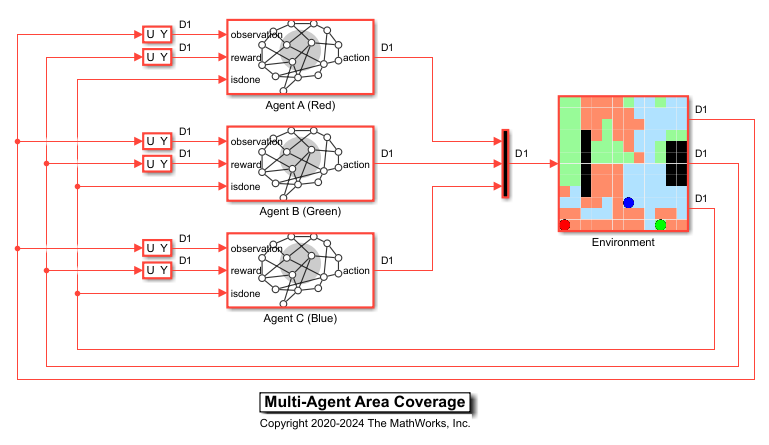

open_system(mdl+"/Environment")

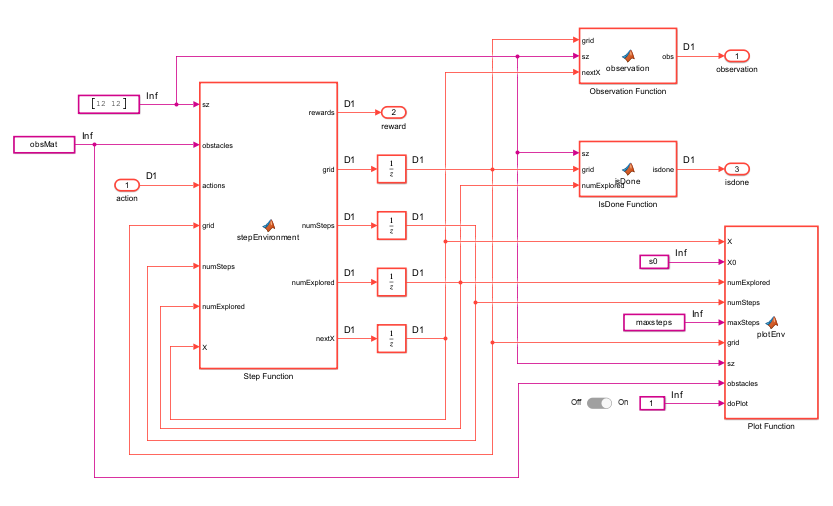

% Define observation specifications.
obsSize = [12 12 4];
oinfo = rlNumericSpec(obsSize);
oinfo.Name = "observations";

% Define action specifications.
numAct = 5;
actionSpace = {0,1,2,3,4};
ainfo = rlFiniteSetSpec(actionSpace);
ainfo.Name = "actions";

% Block paths for agents
blks = mdl + ["/Drone A (Cyan)","/Drone B (Magenta)","/Drone C (Yellow)"];

% Environment interface, same obsrvation and actions for all agents
env = rlSimulinkEnv(mdl,blks,{oinfo,oinfo,oinfo},{ainfo,ainfo,ainfo});

% Update the reset function to randomize obstacles every reset
env.ResetFcn = @(in) resetMap(in, gridSize, numObstacles, randomizeObstacles);

function in = resetMap(in, gridSize, numObstacles, randomizeObstacles)
    if randomizeObstacles
        % Randomize obstacle locations within the grid
        obsMat = zeros(numObstacles, 2); % Preallocate for speed
        for i = 1:numObstacles
            obsMat(i, :) = randi([1 gridSize(1)], 1, 2);
        end
    else
        % Fixed obstacle locations
        obsMat = [ ...
            4 3; ...
            4 4; ...
            6 4; ...
            7 4; ...
            8 4; ...
            9 4; ...
            5 10; ... 
            6 11; ...
            7 11; ...
            8 10; ...
            5 12; ...
            6 12; ...
            7 12; ...
            8 12 ];
    end
    
    g0 = zeros(gridSize);
    for idx = 1:size(obsMat,1)
        r = obsMat(idx,1);
        c = obsMat(idx,2);
        g0(r,c) = 1.0;
    end
    
    % Initial robot positions (cyan, magenta, yellow)
    sA0 = [2 2];
    sB0 = [11 4];
    sC0 = [3 12];
    
    g0(sA0(1),sA0(2)) = 0.2; % Drone A (Cyan)
    g0(sB0(1),sB0(2)) = 0.4; % Drone B (Magenta)
    g0(sC0(1),sC0(2)) = 0.6; % Drone C (Yellow)
    
    % Update the environment with the new grid
    
    in = setVariable(in, 's0', s0);
    in = setVariable(in, 'g0', g0);

end

% Create actor deep neural network.
actorNetWork = [
    imageInputLayer(obsSize)
    convolution2dLayer(3,16,Padding="same",PaddingValue=-1,Stride=2)
    reluLayer
    maxPooling2dLayer(3,Padding="same",Stride=2)
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(numAct)
    softmaxLayer
    ];
actorNetWork = dlnetwork(actorNetWork);

% Create critic deep neural network.
criticNetwork = [
    imageInputLayer(obsSize)
    convolution2dLayer(3,16,Padding="same",PaddingValue=-1,Stride=2)
    reluLayer
    maxPooling2dLayer(3,Padding="same",Stride=2)
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(1)
    ];
criticNetwork = dlnetwork(criticNetwork);


% Create actor and critic objects
for idx = 1:3
    actor(idx) = rlDiscreteCategoricalActor(actorNetWork,oinfo,ainfo,UseDevice="gpu");
    critic(idx) = rlValueFunction(criticNetwork,oinfo,UseDevice="gpu");
end

actorOpts  = rlOptimizerOptions(LearnRate=1e-3, GradientThreshold=1, L2RegularizationFactor=1e-4);
criticOpts = rlOptimizerOptions(LearnRate=1e-3, GradientThreshold=1, L2RegularizationFactor=1e-4);

opt = rlPPOAgentOptions(...
    ActorOptimizerOptions=actorOpts,...
    CriticOptimizerOptions=criticOpts,...
    ExperienceHorizon=1000,...
    MiniBatchSize=200,...
    SampleTime=Ts,...
    DiscountFactor=0.9);

agentA = rlPPOAgent(actor(1),critic(1),opt);
agentB = rlPPOAgent(actor(2),critic(2),opt);
agentC = rlPPOAgent(actor(3),critic(3),opt);

trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups",{[1,2,3]},...
    "LearningStrategy","centralized",...
    MaxEpisodes=500,...
    MaxStepsPerEpisode=maxsteps,...
    SimulationStorageType="none",...
    ScoreAveragingWindowLength=20,...
    StopTrainingCriteria="AverageReward", ...
    StopTrainingValue=200);

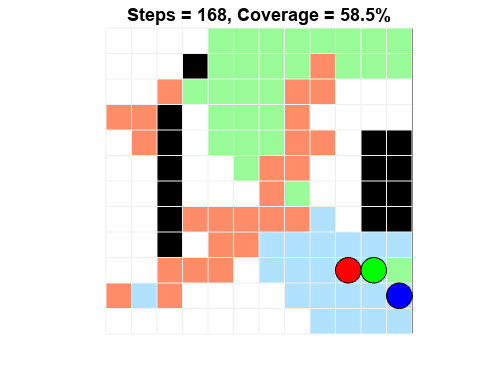

loadWeights = false;
if ~loadWeights
    result = train([agentA,agentB,agentC],env,trainOpts);
else
    load("rlAreaCoverageAgents.mat","params");
    % The saved agents were trained in centralized manner with synchronized
    % model parameters. Set the trained parameters on all agents.
    setLearnableParameters(agentA, params);
    setLearnableParameters(agentB, params);
    setLearnableParameters(agentC, params);
end

## Simulate Agents

Reset the random seed for reproducibility.

rng(0)

Simulate the trained agents within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOpts = rlSimulationOptions(MaxSteps=maxsteps);
experience = sim(env,[agentA,agentB,agentC],simOpts);

The agents are able to achieve full coverage of the grid world.

*Copyright 2020-2024 The MathWorks, Inc.*